# CLASE >> Transformada Z

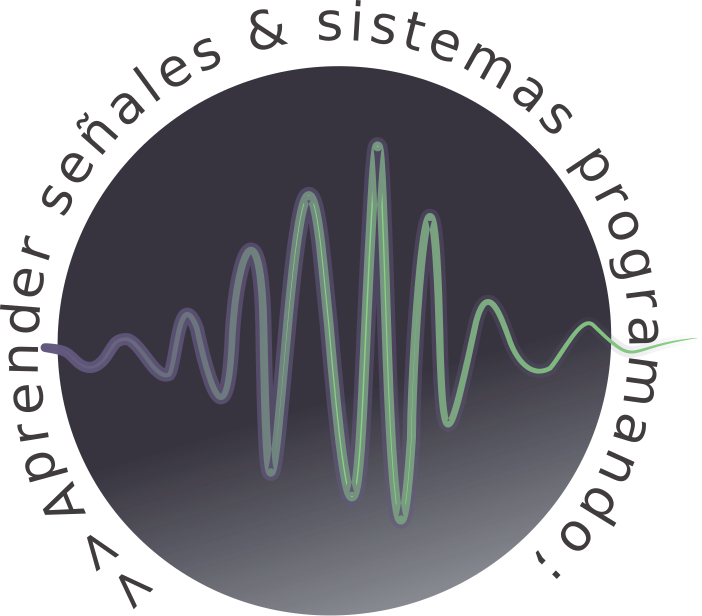

# Temario

- Introducción

- Definición

- Propiedades

- Transformada inversa

- Función transferencia

- Respuesta en frecuencia a partir de la función transferencia

# Introducción

La **transformada Z** es un operador matemático que funciona como contrapartida de la transformada de Laplace pero en el dominio de las señales y los **sistemas discretos**. 

Gran parte del contenido que se analiza en este apunte contiene una similitud muy importante con el contenido trabajado en el apunte sobre la transformada de Laplace; como se verá en el desarrollo sucesivo, la transformada Z también es un operador de gran utilidad para llevar a cabo la caracterización de un **sistema lineal, causal e invariante en el tiempo**, pero en este caso de sistemas discretos. 

# Definición

La transformada Z es una generalización de la transformada de Fourier de tiempo discreto, tal como la transformada de Laplace es una generalización de la transformada de Fourirer de tiempo continuo. La misma está formulada de la siguiente manera:

en donde:

Se conoce como** transformada bilateral** cuando se trabaja con el intervalo de tiempo discreto de menos infinito a más infinito; de todas maneras, es común, cuando se está en presencia de sistemas causales, trabajar con la **transformada unilateral **en la cual sólo se trabajan con valores de tiempo mayores o iguales a cero. 

Como en el curso se trabajan con sistemas causales, se abordará solamente el estudio de la transformada unilateral. Por lo tanto, de ahora en más, se llamará transformada z a:

Los valores de z para los cuales la sumatoria converja forman parte de la **región de convergencia** de la transformada Z. 

## Ejemplo: transformadas básicas

% ¿Cuál es la transformada z del impulso unitario?

syms n z

assume(in(n, 'integer') & n > 0)

x = kroneckerDelta(n);
X = ztrans(x, n, z)

$$X = 0$$

% Lo cual es fácilmente corroborable. 

% ¿La transformada z del impulso unitario desplazado hacia la derecha?

syms q

assume(in(q, 'integer') & q > 0)

x = kroneckerDelta(n-q);

X = ztrans(x, n, z)

$$X = \frac{1}{z^{q}}$$

% ¿Cuál es la transformada del escalón unitario?

x = heaviside(n);

X = ztrans(x, n, z)

$$X = \frac{z}{z-1}$$

% ¿Cuál es la transformada de la señal exponencial?

syms a

x = a^n*heaviside(n);

X = ztrans(x, n, z)

$$X = -\frac{z}{a-z}$$

# Propiedades

La transformada Z posee ciertas propiedades que serán analizadas a continuación; a partir de las mismas es posible hallar mayor cantidad de pares de transformadas a partir de las básicas ya demostradas.

## Linealidad

Al igual que el resto de los operadores estudiados, la transformada Z es un operador matemático lineal; esto significa que de tener dos secuencias discretas con transformada Z:            

Cualquier combinación lineal de ellas tendrá como transformada a la misma combinación lineal de sus respectivas transformadas. 

syms n a
assume(n, 'integer')
assume(a ~= 1)
x = heaviside(n);
v = a^n*heaviside(n);
isequal(ztrans(x + v),ztrans(x) + ztrans(v))

ans =    1


## Desplazamiento por la derecha

Supóngase que se tiene una secuencia discreta con transformada Z. 

Entoces, siendo q un entero positivo:

syms n z
assume(n, 'integer')
p(n) = heaviside(n-1);
isequal(ztrans(p),z^(-1)*ztrans(heaviside(n)))

ans =    1


## Multiplicación por n y n al cuadrado

Existe otra propiedad que establece que, de tenerse una secuencia discreta con transformada Z

entonces,

syms n z
assume(n, 'integer')
x = heaviside(n);
isequal(ztrans(n*x),-z*diff(ztrans(x)))

ans =    1


## Convolución

Como en el resto de los operadores estudiados, una convolución de secuencias discretas en el dominio temporal implica una multiplicación en el dominio de la transformada Z.

# Transformada inversa

Si se conoce la expresión de una función en el dominio Z, puede obtenerse a la secuencia discreta en el dominio temporal a partir de la transformada inversa. La misma tiene la siguiente expresión matemática:

Esta integral no es nada sencilla de calcular. Afortunadamente, para los casos en que la transformada X(z) está expresada como una función racional, es posible obtener x[n] a partir de la expansión en serie de potencias o en fracciones simples. 

*Fracciones simples*

Como se estableció anteriormente, no son pocas las situaciones en las que la expresión en el dominio Z de cierta señal viene dada de la siguiente forma:

Cuando el grado del polinomio del denominador es mayor que el grado del numerador, la expresión puede desarrollarse a partir de la expansión por fracciones simples. De no ser ese el caso, pueden dividirse los polinomios hasta obtener una expresión como la siguiente:

en donde se tendría en el segundo de los términos sumandos una razón que podría expandirse en fracciones simples. 

Si, por ejemplo, el grado de ambos polinomios es el mismo, puede expandirse la siguiente función:

en el caso de ser polos distintos de cero y diferentes entre sí la expresión anterior es equivalente a la siguiente:

en donde los residuos tienen las expresiones siguientes:

Multiplicar por z a ambos lados del igual de la expresión anterior permite obtener una expresión de la señal en el dominio Z:

Cada uno de los términos sumandos tienen una transformada inversa conocida, lo que permite obtener la expresión temporal de la señal de manera inmediata:

Esta expresión permite concluir de manera terminante que los polos de X(z) determinan el aspecto de la señal en el dominio temporal. Los polos pueden ser reales o complejos; en el caso de tenerse polos complejos, los mismos siempre aparecen de a pares conjugados, por lo tanto en la expresión de x[n] terminan combinándose de forma tal que la función está valuada en reales. 

## Ejemplo

Supóngase que se tiene la siguiente transformada racional:

syms z
B = z^3 + 1;
A = z^3 - z^2 - z - 2;
X(z) = B/A;
digitsOld = digits(3);
polos = vpa(root(A)) % Polos de X(z).

$$polos = \left(\begin{array}{c} 2.0\\ -0.5-0.866\,\mathrm{i}\\ -0.5+0.866\,\mathrm{i} \end{array}\right)$$

Con los polos conocidos, puede expresarse el denominador de forma factorizada. Dividir X(z) por z, permite trabajar con lo expuesto anteriormente; para hacer uso de las relaciones anteriormente establecidas se necesita conocer los valores de los residuos correspondientes.

A = factor(A,'FactorMode','complex')

$$A = \left(\begin{array}{ccc} z-2.0 & z+0.5+0.866\,\mathrm{i} & z+0.5-0.866\,\mathrm{i} \end{array}\right)$$

% Residuos
c0 = X(0)

$$c0 = -\frac{1}{2}$$

den = A;
for i = 1:length(polos)
    den(i) = 1;
    r(z) = B/(prod(den)*z);
    residuos(i) = r(polos(i));
    den = A;
end 

residuos = [c0, residuos]   

$$residuos = \left(\begin{array}{cccccc} -\frac{1}{2} & 0.643 & 0.429+0.0825\,\mathrm{i} & 0.429-0.0825\,\mathrm{i} & 0.429-0.0825\,\mathrm{i} & 0.429-0.0825\,\mathrm{i} \end{array}\right)$$

Podemos construir la transformada X(z) en expandida en fracciones simples de la siguiente manera:

terminos = [residuos(1)];
for i = 1:length(polos)
    terminos(i + 1) = (z*residuos(i + 1))/(A(i));
end

X = sum(terminos)

$$X = \frac{0.643\,z}{z-2.0}+\frac{z\,\left(0.429+0.0825\,\mathrm{i}\right)}{z+0.5+0.866\,\mathrm{i}}-\frac{1}{2}+\frac{z\,\left(0.429-0.0825\,\mathrm{i}\right)}{z+0.5-0.866\,\mathrm{i}}$$

x = iztrans(X)

$$x = 0.643\,2.0^{n}-0.5\,\delta_{n,0}+{\left(-0.5-0.866\,\mathrm{i}\right)}^{n-1}\,\left(-0.143-0.412\,\mathrm{i}\right)+{\left(-0.5+0.866\,\mathrm{i}\right)}^{n-1}\,\left(-0.143+0.412\,\mathrm{i}\right)$$

Se ve que el resultado obtenido es idéntico al desarrollado teóricamente en el apartado anterior. Con el uso de estos algoritmos es posible llevar a cabo la construcción de un programa que calcule analíticamente la antitransformada de una transformada compuesta por la razón de dos polinomios. 

# Función transferencia

Ya se ha comentado en apuntes anteriores la importancia de la función transferencia a la hora de caracterizar a los sistemas lineales e invariantes en el tiempo; la transformada Z permite llevar a cabo ese tipo de análisis para el caso de los sistemas de variable discreta. Estos sistemas pueden definirse por ecuaciones en diferencias de entrada y salida.

## Primer orden

Los sistemas LTI representados en ecuaciones de diferencias de primer orden tienen la siguiente expresión:

Esta expresión puede ser transformada al dominio z; se obtiene:

Para simplificar la situación, de establecerse condiciones iniciales nulas, se podría despejar a la relación entre la salida y la entrada, la cual se llama función transferencia del sistema:

De la cual se infiere que:

## Segundo orden

Un sistema LTI representado en una ecuación de diferencias de segundo orden tiene la siguiente expresión:

Esta expresión puede ser transformada al dominio z; se obtiene:

Para simplificar la situación, de establecerse condiciones iniciales nulas, se podría despejar a la relación entre la salida y la entrada, la cual se llama función transferencia del sistema:

## Ejemplo

Supóngase que se tiene el siguiente sistema LTI expresado en una ecuación de diferencias de segundo orden.

Una forma muy sencilla de trabajar con sistemas digitales en Matlab es con la utilización de la función **filter**. A partir de la ecuación en diferencias, pueden declararse dos vectores correspondientes a el numerador y denominador de la función transferencia.

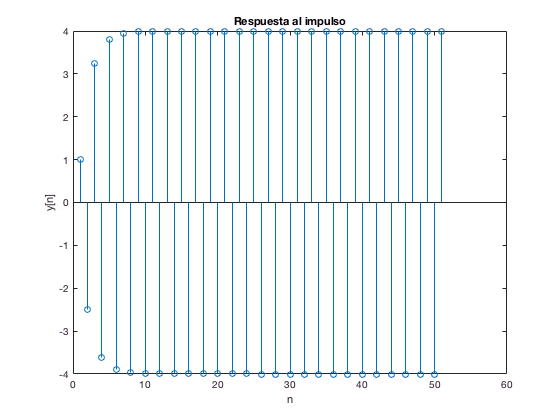

B = [1, -1, 0];
A = [1, 1.5, 0.5];

% Para poder visualizar la respuesta al impulso
x = [1, zeros(1,50)];
y = filter(B,A,x);

stem(y); title('Respuesta al impulso'); xlabel('n'); ylabel('y[n]')

Si el sistema discreto está dado por una ecuación en diferencias, entonces, su función transferencia es una función racional valuada en complejos. Por definición, se dice que este tipo de sistemas son **dimensionalmente finitos.**

# **Respuesta en frecuencia a partir de función transferencia**

La función de respuesta en frecuencia de un sistema LTI puede ser obtenida a partir de la función transferencia. Considerando que la función transferencia tiene la siguiente expresión:

Al establecer que la magnitud de la variable independiente sea 1 y su fase sea una variable real perteneciente al conjunto que va desde 0 a pi, se especifica a la función a ser la respuesta en frecuencia del sistema en cuestión. 

Consideremos como sistema LTI a un filtro digital causal pasa bajos muy sencillo:

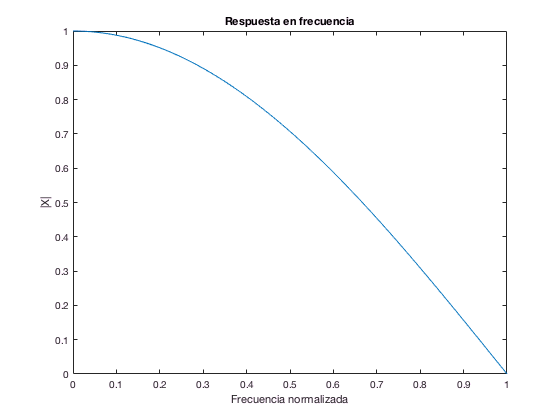

% variable independiente
omega = (0:0.01:1);
w = pi.*omega;
z = exp(j*w);

% función transferencia
H = (1/2)*z.^2+(1/2)*z;

% función magnitud
magH = abs(H);

% función fase
angH = 180/pi*unwrap(angle(H));

figure(1)
plot(omega, magH); title('Respuesta en frecuencia'); xlabel('Frecuencia normalizada');
ylabel('|X|')
hold off

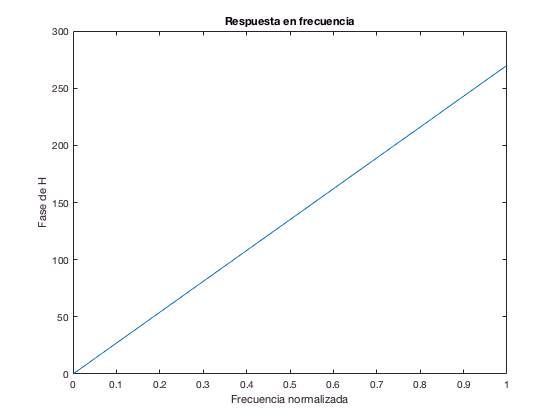


figure(2)
plot(omega, angH); title('Respuesta en frecuencia'); xlabel('Frecuencia normalizada');
ylabel('Fase de H')
hold off

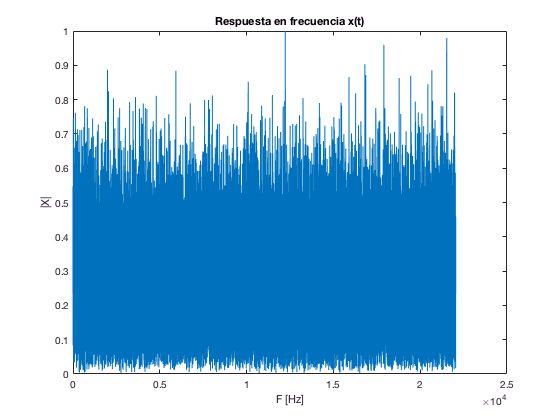


% Si, por ejemplo, generamos dos segundos de ruido blanco:

t = 0:1/44100:2-1/44100;

x = randn(1,length(t));

% Y lo filtramos con el sistema que establecimos, se obtiene y

y = filter([1/2 1/2],1,x);

% Puede visualizarse la respuesta en frecuencia tanto de la entrada 
% como de la salida del filtro para ver cómo es que el mismo afecta a una señal
% de banda ancha.

X = fft(x);
L = length(x);
X = abs(X/max(X));
X = X(1:L/2+1);
f = 44100*(0:(L/2))/L;
plot(f,X); title('Respuesta en frecuencia x(t)'); ylabel('|X|'); xlabel('F [Hz]')

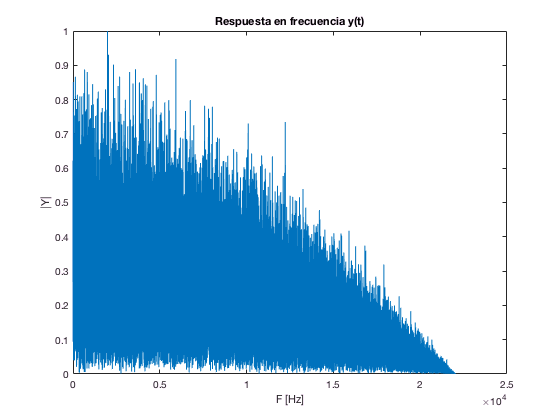


Y = fft(y);
L = length(y);
Y = abs(Y/max(Y));
Y = Y(1:L/2+1);
f = 44100*(0:(L/2))/L;
plot(f,Y); title('Respuesta en frecuencia y(t)'); ylabel('|Y|'); xlabel('F [Hz]')

## Referencias

- Kamen, Edward W., and Bonnie S. Heck. ***Fundamentos de señales y sistemas usando la Web y Matlab***. Pearson Prentice-Hall, 2008.

- Oppenheim, Alan V.; Willsky, Alan S.; Nawab, S. Hamid. ***Señales y sistemas***. Pearson Educación, 1998.